## Obtenga las imágenes y las clases de entrenamiento:

1.Cree un almacén de datos para las imágenes que están en la carpeta `WormImages`.

ds_lombris = imageDatastore('WormImages/*worm*.tif')

ds_lombris =   ImageDatastore with properties:

                       Files: {
                              ' ...\Juan Esteban\Documents\MATLAB\prorecto 2\ProDL\WormImages\wormA01.tif';
                              ' ...\Juan Esteban\Documents\MATLAB\prorecto 2\ProDL\WormImages\wormA02.tif';
                              ' ...\Juan Esteban\Documents\MATLAB\prorecto 2\ProDL\WormImages\wormA03.tif'
                               ... and 90 more
                              }
                     Folders: {
                              'C:\Users\Juan Esteban\Documents\MATLAB\prorecto 2\ProDL\WormImages'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


2.Obtenga las clasificaciones conocidas del archivo `WormData.csv`y utilícelas como etiquetas de imagen.

clasificacion=readcell('WormData.csv','Range','B2:C94');
clasificacion=categorical(clasificacion);
ds_lombris.Labels=clasificacion;

3. Muestre las primeras 3 imágenes.

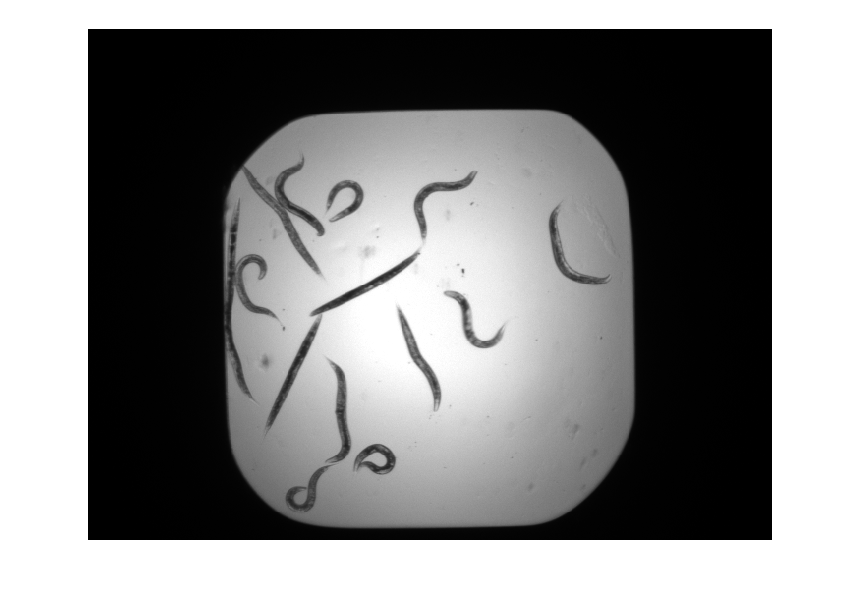

img1=readimage(ds_lombris,1);
imshow(img1)

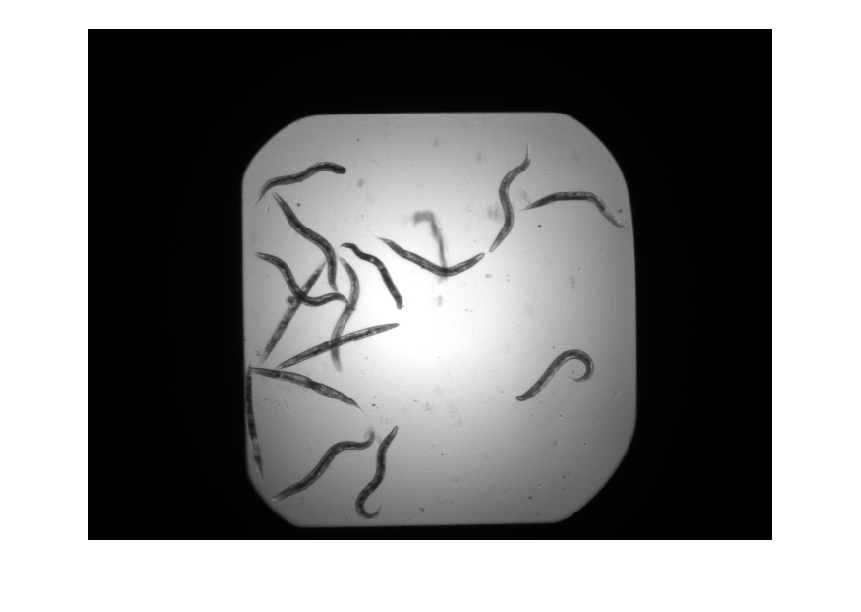

img2=readimage(ds_lombris,2);
imshow(img2)

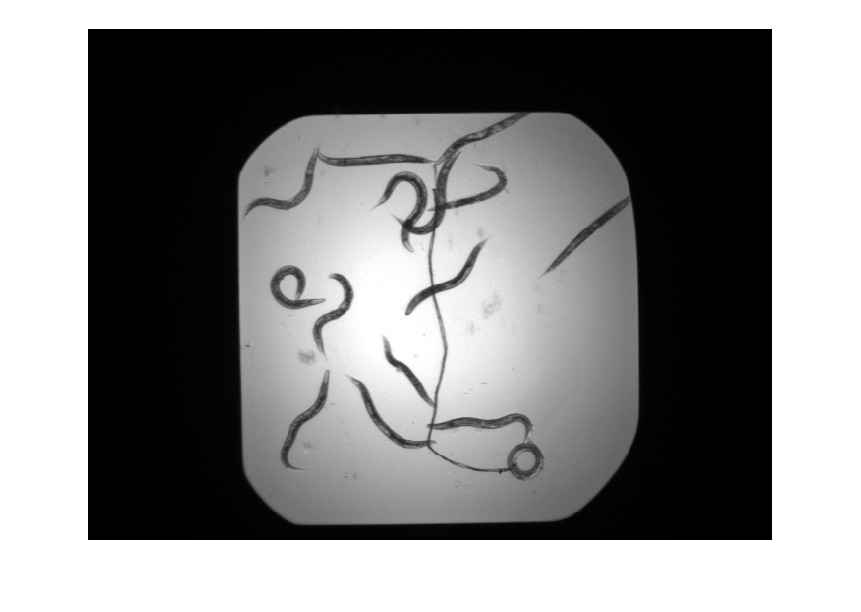

img3=readimage(ds_lombris,3);
imshow(img3)

4.Divida los datos en conjuntos de entrenamiento (60%) y prueba (40%).

[lombris_entrena,lombris_prueba]=splitEachLabel(ds_lombris,0.6);

lombris_entrena_au = augmentedImageDatastore([224 224 3],lombris_entrena,...
                'ColorPreprocessing','gray2rgb')

'augmentedImageDatastore' requires Deep Learning Toolbox.

lombris_prueba_au = augmentedImageDatastore([224 224 3],lombris_prueba,...
                'ColorPreprocessing','gray2rgb')

5.Cree almacenes de datos de imágenes aumentados para preprocesar las imágenes.

ds_lombris_au = augmentedImageDatastore([224 224 3],ds_lombris,...
                'ColorPreprocessing','gray2rgb')

## Construyauna red:

6.Comience con la red previamente entrenada GoogleNet

red_neu = googlenet;                % hacemos el llamado de la red
capas = red_neu.Layers;             % Extraemos las capas de la red
cap_entrada = red_neu.Layers(1)     % Estraemos la primer capa
tam_entrada = cap_entrada.InputSize;% Estraemos el tamaño de entrada de la red
cap_salida = red_neu.Layers(end);   % Capa de salida de la red    
categorias = cap_salida.Classes;    % Extraemos las clases de las salidas de la red
num_clases=numel(categorias(ds_lombris.Labels));


7 .Cree una nueva capa completamente conectada con 2 neuronas

lgraph = layerGraph(red_neu)
newFc = fullyConnectedLayer(2,"Name","new_fc")

8.Sustituya la última capa totalmente conectada de la red con la nueva capa recién creada.

lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

9.Sustituya la capa final de la red con una nueva capa de clasificación.

newOut = classificationLayer("Name","new_out")
lgraph = replaceLayer(lgraph,"output",newOut)

## Establezca algunas opciones de entrenamiento:

10.Cree  una  variable  con  las  opciones  predeterminadas  del  algoritmo  de  entrenamiento  para  el optimizador SGDM, excepto para la opción `InitialLearnRate`, que debe establecerse como `0.001`.    

op_entrena= trainingOptions('sgdm','InitialLearnRate', 0.001);

## Entrene la red:

11.Entrene la red.

[red_lombris,info]=trainNetwork(lombris_entrena_au, lgraph, op_entrena);

## valúe la red con datos de prueba:

12.Haga predicciones y compare con la realidad.

Predicciones = classify(red_lombris,lombris_prueba_au)

13.Muestre la matriz de confusión.

Matr.Conf = confusionchart(lombris_prueba.Labels,Predicciones) 


Nota:Si dispone de una GPU soportada, podrá entrenar su red en menos de un minuto. También puede  entrenar  su  red  en  una  CPU,  pero  el  proceso  de entrenamiento  puede  llevar  hasta  diez minutos

%{
tam_img=size(img3)  
tam_ds_au=size(ds_lombris_au)
ls WormImages/*.tif;                % Carga las imagenes             
montage(ds_lombris);
nombres=ds_lombris.Files;
tabla= readtable("WormData.csv");
%}

